%figure 3
c_gains=logspace(-4,3,25)

c_gains = 	1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0006    0.0012    0.0024    0.0046    0.0091    0.0178    0.0348    0.0681    0.1334    0.2610    0.5109    1.0000


plot_list2=[]


plot_list2 =

     []



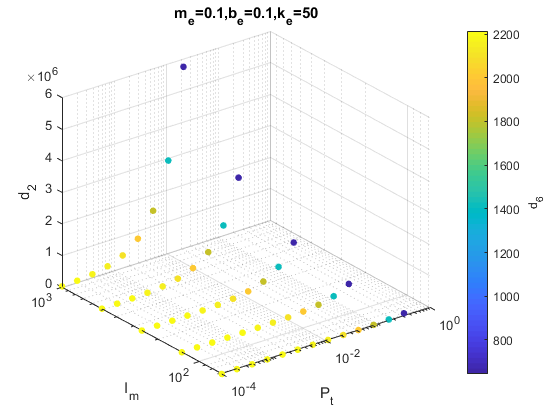

b_e=0.1;
m_e=0.1;
k_e=50;
for i=1:length(c_gains)
    for j=1:length(c_gains)
        P_t=c_gains(i);
        I_m=c_gains(j);
        passivityCheck;
        if passivity==1
                   plot_list2=[plot_list2;P_t I_m eval(beta) eval(a_2) eval(a_6)];
        end
    %plot_beta(i,j)=eval(beta);
    %plot_a_2(i,j)=eval(a_2);
    %plot_a_6(i,j)=eval(a_6);
    end
end
figure
% subplot(1,3,3);
% contourf(c_gains,c_gains,plot_beta,[0 0],'ShowText','on')
% xlabel('P_{t}') 
% ylabel('I_{m}')
% set(gca, 'YScale', 'log')
% set(gca, 'XScale', 'log')
% title('\beta') 


scatter3(plot_list2(:,1),plot_list2(:,2),plot_list2(:,4),25,plot_list2(:,5),'filled')
xlabel('P_{t}') 
ylabel('I_{m}')
zlabel('d_{2}')
set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')
title('m_e=0.1,b_e=0.1,k_e=50') 
colorbar
ylabel(colorbar, 'd_{6}')

% subplot(1,2,2);
% contourf(plot_list2(:,1),plot_list2(:,2),Z2,[0 0],'ShowText','on')
% xlabel('P_{t}') 
% ylabel('I_{m}') 
% set(gca, 'YScale', 'log')
% set(gca, 'XScale', 'log')
% title('d_6') 
% figure
% contourf(c_gains,c_gains,plot_k_e,'ShowText','on')
% xlabel('P_{t}') 
% ylabel('I_{m}') 
% set(gca, 'YScale', 'log')
% set(gca, 'XScale', 'log')
% contourf(c_gains,c_gains,plot_m_e)
% xlabel('P_{t}') 
% ylabel('I_{m}') 
% contourf(c_gains,c_gains,plot_routh,[0 0],'ShowText','on')
% xlabel('P_{t}') 
% ylabel('I_{m}') 
